clc 
clear all
close all

load '2Class_KNN_Data-1 (1).mat'

x_train = cat(1,c1,c2)

x_train =     0.1164    0.8673
    0.2454    0.8790
    0.1970    0.7653
    0.1118    0.6691
    0.2638    0.6458
    0.4551    0.7624
    0.6348    0.8440
    0.6417    0.8207
    0.6025    0.6866
    0.7108    0.7012


y_train = cat(1, zeros(100,1),ones(100,1))

y_train =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


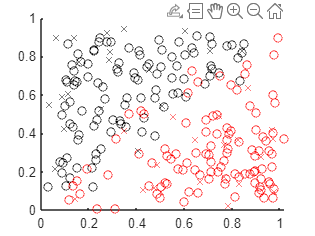


x_test = cat(1, c1test, c2test);
y_test = cat(1, zeros(20,1), ones(20,1));

% scatter((1:200), c1, 'o', 'black');
% hold on
% scatter((1:200), c2, 'o', 'Red');
% hold on
% scatter((1:20), c1test(:,1), 'o', 'black');
figure
scatter(x_train((1:100),1), x_train((1:100),2), 'o', 'black')
hold on
scatter(x_train((101:200),1), x_train((101:200),2), 'o', 'red')
hold on
scatter(x_test((1:20),1), x_test((1:20),2), 'x', 'black')
hold on
scatter(x_test((21:40),1), x_test((21:40),2), 'x', 'red')
hold off

md1 = fitcknn(x_train, y_train)

md1 =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 200
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods





y_pred = predict(md1, x_test)

y_pred =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0



m = confusionmat(y_test, y_pred)

m =     19     1
     2    18



classError = 1 - (sum(diag(m), 'all'))/(sum(m,'all'))

classError = 0.0750

Problem 2: Color Image Segmentation Using K-means Algorithm

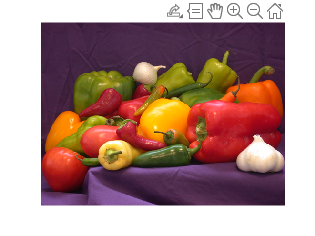

I = imread("peppers.png");

imshow(I);

%use the columns as the color channels 
r = I(:,:,1);
g = I(:,:,2);
b = I(:,:,3);
iter = 1
K = 3
meansClusters = zeros(1,K)
C_one = 0;
C_two = 0;
C_three = 0;
%randomly sample K data points
[y1, idx] = datasample(I(:,:,:), K, 'Replace', false)

while(true)
    iter = 1
    C_one = 0;
    C_two = 0;
    C_three = 0;
    %randomly sample K data point

    for i = 1:size(I,1)
        for j = 1:size(I,2)        
            s1 = y1(:, idx);
            s2 = y1(:, idx);
            s3 = y1(:, idx);
    
            dist1 = sqrt(sum((s1(1,:) - [i,j]).^2));
            dist2 = sqrt(sum((s2(2,:) - [i,j]).^2));
            dist3 = sqrt(sum((s3(3,:) - [i,j]).^2));
    
            small = min(dist1, dist2, dist3);
            if small == dist1
                C_one = C_one + r(i,j) + g(i,j) + b(i,j)
            elseif small == dist2
                C_two = C_two + r(i,j) + g(i,j) + b(i,j) 
            else 
                C_three = C_three + r(i,j) + g(i,j) + b(i,j)
            end
            
        end
    end
    m_one = mean(C_one);
    m_two = mean(C_two);
    m_three = mean(C_three);

    if((idx(1) == m_one) &&  (idx(2) == m_two) && (idx(3) == m_three))
        break
    else
        s1 = m_one;
        s2 = m_two; 
        s3 = m_three;
        iter = iter + 1;
    end
end

[L, C] = imsegkmeans(I, 5)

L = 384×512 uint8 matrix
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   

C = 5×3 uint8 matrix
    69    40    60
   144    92   127
   239   210   174
   178    38    33
   182   131    22


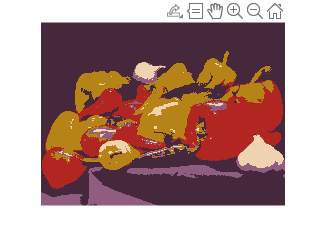

imshow(label2rgb(L, im2double(C)))